# Demo of the Symbolic Math Toolbox

Made by Simon Thor, MATLAB student ambassador at KTH (2021).

## Installation

Press the "Get more apps" button under the "Apps" section in MATLAB. This will open up a new window. Search for "Symbolic math toolbox" and it should appear. From there, you can download the toolbox by following the instructions given in MATLAB.

## Crash course on the live editor

I (and MathWorks) recommends using the symbolic math toolbox is easiest to use in the live editor (i.e. the interface you are looking at now) instead of plain `.m` files. Live scripts contain sections that you can run individually by pressing `Ctrl+Enter` (on Windows)`.` You can try it out here:

a = 1

a =      1


a + 5

ans =      6


The ouput is displayed to the right. 

Sections can be created with `Ctrl+Alt+Enter`.

## Introduction to the Symbolic Math Toolbox

### Basics

You can create symbolic values with the `sym` command:

sym(pi)

$$ans = \pi$$

sym(2/3)

$$ans = \frac{2}{3}$$

2/3

Note how it is displayed in the output, compared to a numerical value.

You can create symbolic variables with the `syms` command:

syms x

or create multiple variables at the same time:

syms a b c y

$$a\_1 = a_{1}$$

$$b\_minor = b_{\mathrm{minor}}$$

$$c2 = c_{2}$$

You can then perform normal operations on variables and numbers to create symbolic expressions.

y = a*x^2 - b*5/3/sqrt(c)

$$y = a\,x^{2}-\frac{5\,b}{3\,\sqrt{c}}$$

As you can see, the symbolic expression is shown in LaTeX format in the output. This can be copied by right-clicking on the output. You can also paste this into the Live editor:


$$a\,x^2 -\frac{5\,b}{3\,\sqrt{c}}$$


To evaluate for specific values of the variables, you can use `subs:`

subs(y, a, 5) % Substitute one variable

$$ans = 5\,x^{2}-\frac{5\,b}{3\,\sqrt{c}}$$

subs(y, [a b c x], [1 2 3 4]) % Substitute multiple variables

$$ans = 16-\frac{10\,\sqrt{3}}{9}$$

## Modifying Expressions

Symbolic math can be used to solve equations. 

To create a symbolic equation, you cannot use the normal `=`, you instead have to use `==`

syms x
eq = 3*x^4 - 7*x^3 - 37*x^2 - 7*x - 40 == 0

$$eq = 3\,x^{4}-7\,x^{3}-37\,x^{2}-7\,x-40=0$$

$$ans = \left(\begin{array}{ccc} x-5 & 3\,x+8 & x^{2}+1 \end{array}\right)$$

We can then solve this for `x` with the solve function.

solve(eq, x)

$$ans = \left(\begin{array}{c} -\frac{8}{3}\\ 5\\ -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

We get the all answers in a vector. 

### Assumptions

For `eq`, we have both positive, negative and imaginary solutions. If we know something about x, we can use `assume:`

assume(x, 'real')
solve(eq, x)

$$ans = \left(\begin{array}{c} -\frac{8}{3}\\ 5 \end{array}\right)$$

$$ans = 5$$

$$ans = 0<x$$

 
ans =
 
Empty sym: 1-by-0
 


### Live Editor Tasks

Live editor tasks (introduced in R2019b) provides GUIs. They can be found here:

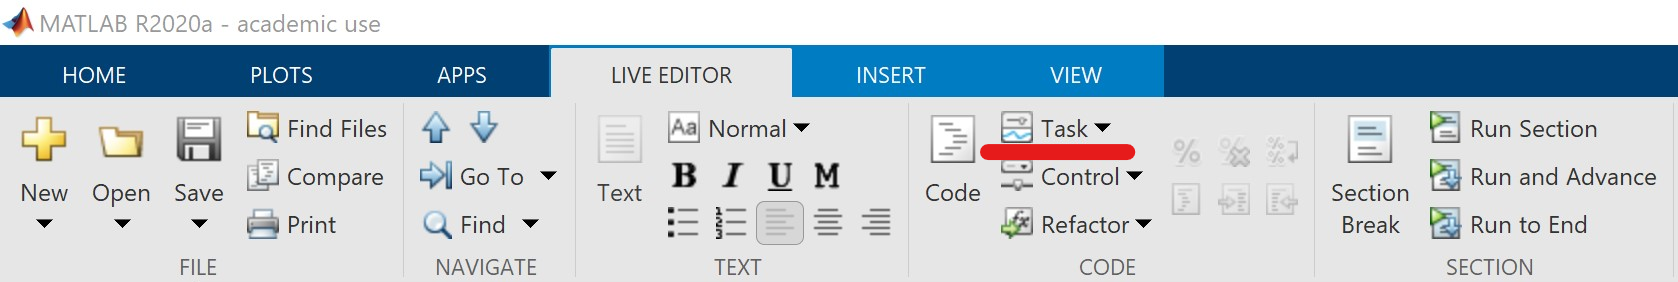

One can be used for solving equations:

% Compute analytic solution of a symbolic equation
solution = solve(eq,x);

Solving equations work when you have multiple symbolic variables too:

solve(a*x^2+b*x+c==0, x)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

Here, we see the classic solution to the quadratic equation.

## Calculus

The Symbolic Math Toolbox can also be used for calculus and differential equations.

The derivative of a function is calculted with `diff`:

syms x
f(x) = x^5

$$f(x) = x^{5}$$

df = diff(f, x)

$$df(x) = 5\,x^{4}$$

We can also calculate the n:th order derivative:

df3 = diff(f, x, 3) % 3rd order derivative

$$df3(x) = 60\,x^{2}$$

Integrals can be calculated with `int:`

int(f, x)

$$ans(x) = \frac{x^{6}}{6}$$

We can also set bounds:

int(f, x, [-1, 5])

$$ans = 2604$$

## Plotting

You can plot symbolic functions in many ways, e.g.

fplot
fimplicit
fplot3
fcontour
fsurf

Here, I plot ${f\left(x\right)=x}^5$ (defined previously)

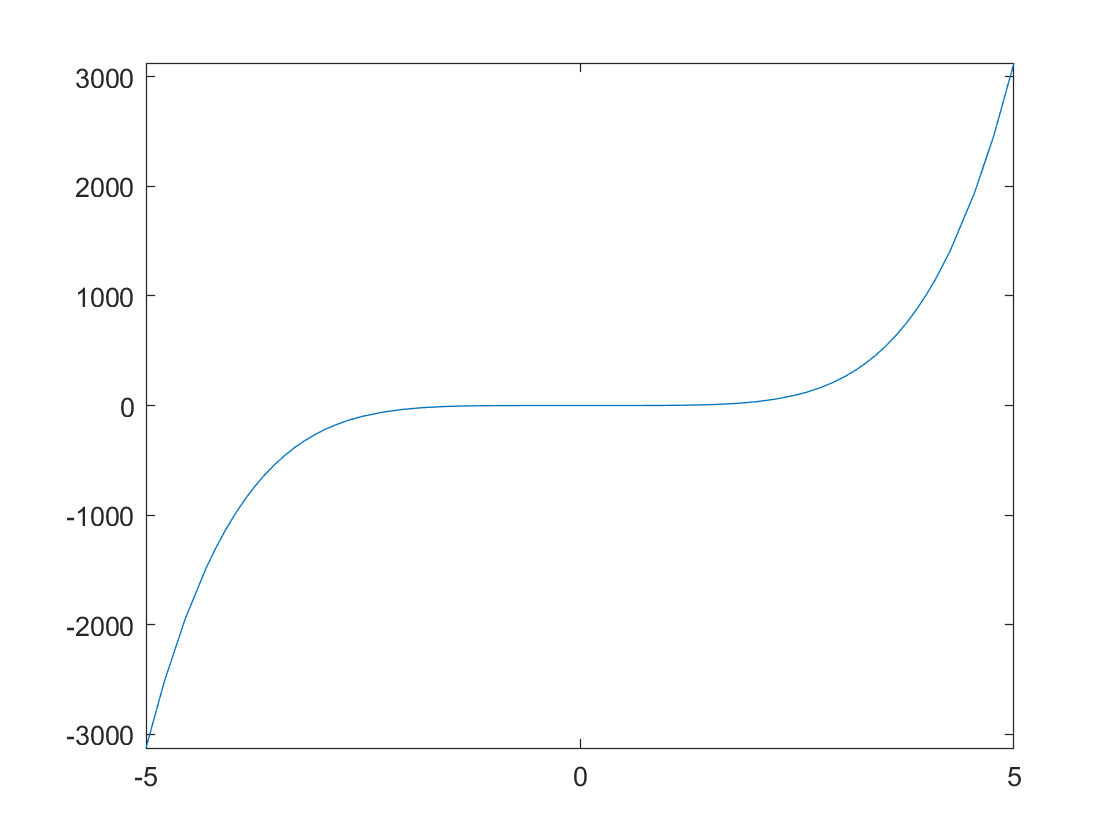

fplot(f)

I only showed a fraction of what can be done with the symbolic math toolbox here. More resources in the [github repo](https://github.com/simonthor/kth-matlab-ambassador/tree/master/Seminars/Symbolic%20Math)!

## Extras

syms x
expr = 2*sin(x)*cos(x)

$$expr = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

simplify(expr)

$$ans = \sin\left(2\,x\right)$$

If you add numbers or text after an underscore (`_`), you can get subscripts on your variables (numbers do not need underscores):

syms a_1 b_minor c2
a_1
b_minor
c2

We can also use comparison operators for assumptions:

assume(x > 0)
solve(eq, x)

$$ans = 5$$

You can clear assumptions:

assumptions(x)

$$ans = 0<x$$

assume(x, 'clear')
assumptions(x)

 
ans =
 
Empty sym: 1-by-0
 
